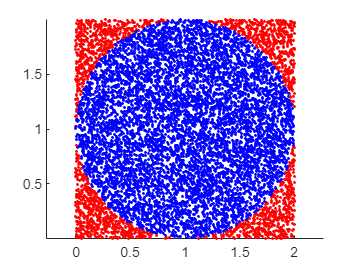

 clc;clear
% 参数初始化：投放10000个点，圆半径为1，圆心坐标(1,1)
% 初始时还未投放点，有0个点在圆内
p = 10000;  r = 1; x0 = 1;  y0 = 1;  n = 0; 
hold on     % 保持绘图窗口，多次绘图
for i = 1:p     % 对于要投放的总共p个点
    % rand函数产生在(0, 1)之间的随机数；rand函数还有其他多种形式，可自行百度
    px = rand*2;    % 随机生成该点的横坐标
    py = rand*2;    % 随机生成该点的纵坐标
    % 所以，
    % 若该点在圆内，则颜色设为蓝色，变量n加一；在圆外则设为红色
    if (px-1)^2 + (py-1)^2 < 1      % 横纵坐标的平方和小于半径，则在圆内
        plot(px,py,'.','Color',"b");
        n = n+1;
    else
        plot(px,py,'.','Color',"r");
    end
end
axis equal      % 绘图时横纵坐标单位长度相同，便于观察圆

s = (n/p)*4;
pi0 = s

pi0 = 3.1420


% 注意：matlab本身有圆周率值，在计算时直接调用pi即可
% a = 2*pi